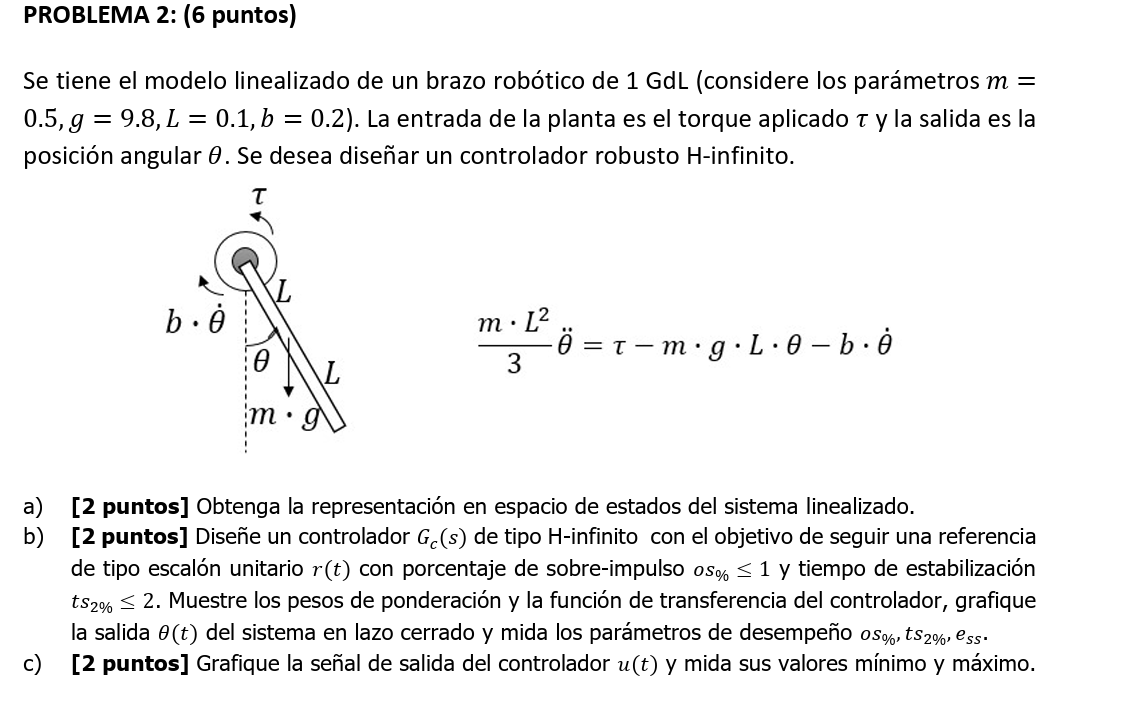

clear all
close all
clc
b=0.2;
m=0.5;
g=9.8;
l=0.1;
A=[0 1;
  -3*(g/l) -3*(b/(m*l^2))]

A =          0    1.0000
 -294.0000 -120.0000


B=[0; 3/(m*l^2)]

B =          0
  600.0000


C=[1 0]

C =      1     0


D=[0]

D = 0

Sp=ss(A,B,C,D)


Sp =
 
  A = 
         x1    x2
   x1     0     1
   x2  -294  -120
 
  B = 
        u1
   x1    0
   x2  600
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model 

Gp=tf(Sp)


Gp =
 
         600
  -----------------
  s^2 + 120 s + 294
 
Continuous-time transfer function.
Model Properties


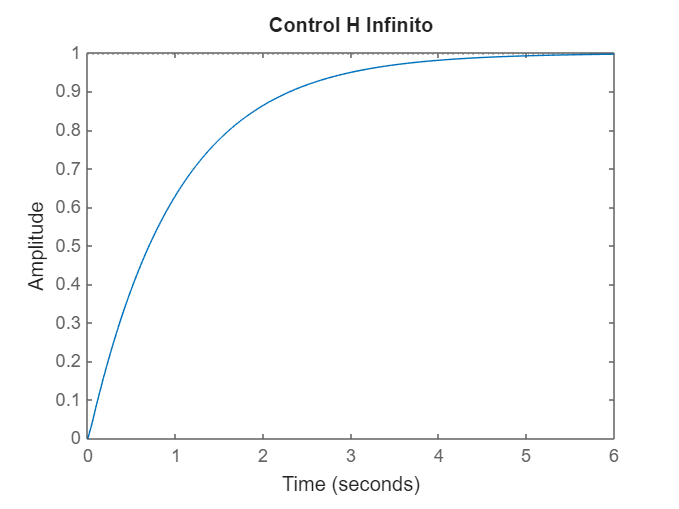

% Configuración de Ponderadores H-Infinito
W1 = makeweight(100, [1, 0.1], 0.01);
W2 = 0.01;
W3 = makeweight(0.01, [1, 0.1], 100);

% Super Planta
P = augw(Gp, W1, W2, W3);

[Sc, CL, gamma] = hinfsyn(P, 1, 1);

Gt = feedback(Gp * Sc, 1);
figure; step(Gt); title('Control H Infinito');

stepinfo(Gt)

ans = struct with fields:
         RiseTime: 2.1875
    TransientTime: 3.9018
     SettlingTime: 3.9018
      SettlingMin: 0.9029
      SettlingMax: 0.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9983
         PeakTime: 7.2903
